calcTto

ans = 0.2136

timeFromDimless(calcTto)

ans = 2.5101

calcVto

ans = 0.9618

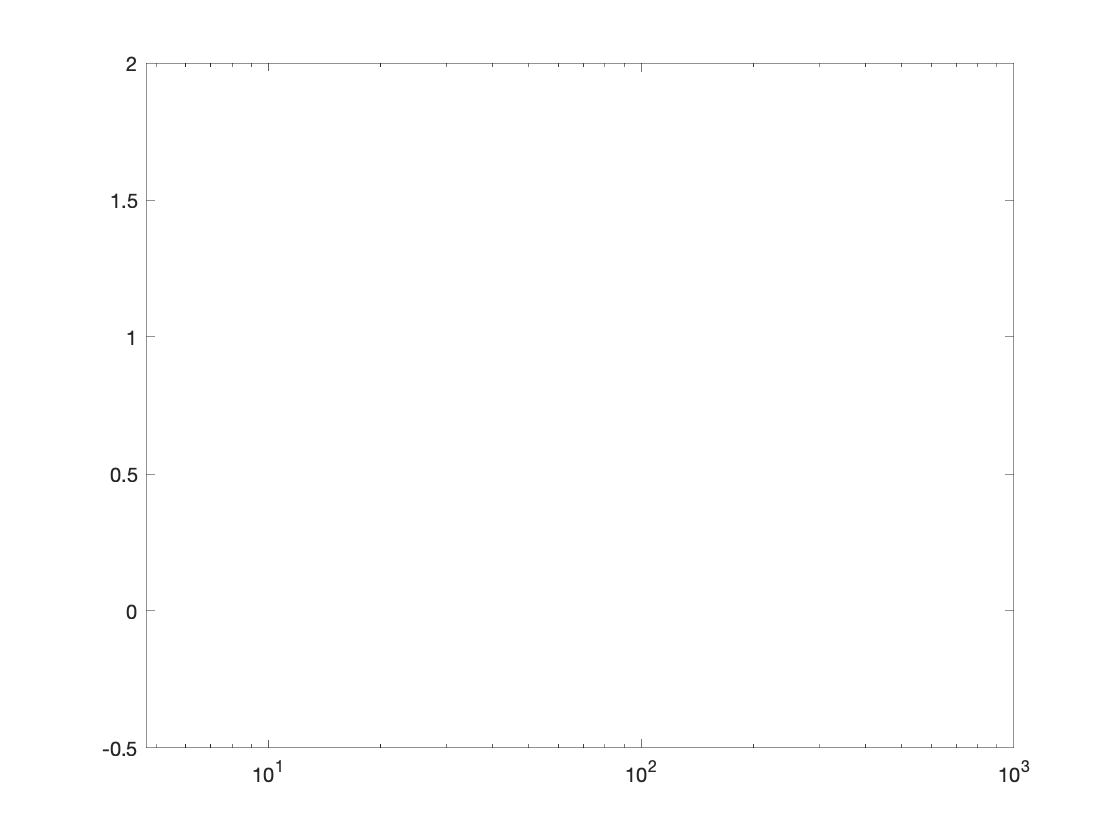


semilogx(mass, calcVto);


% get velocities

function v = calcVto
    v = velFromDimless(1 - exp(calcTto .* -1));
end

% calculate takeoff time (dimensionless)
function tto = calcTto
    tto = fzero(@zerofunc, [0, 1000]);
end

function zf = zerofunc(ttoDl)
    zf = ttoDl + exp(ttoDl .* -1) - distToDimless(d);
end

% constants
function m = mass()
    % values can go from approx 0.50 to 48
    m = logspace(-1, 1.68);
    m = 47;
end

function f = Fmax
    f = 20;
end

function d1 = d
    d1 = 60;
end

function v = vmax
    v = 5;
end

% constants that depend on those constants
function t = tau
    t = mass() * vmax / Fmax;
end

function t = invtau
    t = tau() .^ (-1);
end

% convert from dimension to dimensionless
function t = timeToDimless(time)
    t = (time) ./ tau;
end

function v = velToDimless(vel)
    v = vel ./ vmax;
end

function x = distToDimless(dist)
    x = dist ./ (vmax * tau);
end

% convert from dimensionless to dimension
function t = timeFromDimless(time)
    t = time .* tau;
end

function v = velFromDimless(vel)
    v = vel .* vmax;
end

function x = distFromDimless(dist)
    x = dist .* (vmax * tau);
end